**Ionic Current Model of Bipolar Cells**

Set constants

tspan = [0, 5];

Compute voltage

[tV, res] = calcV(tspan);
V = res(:,5);
res(:,11)

ans = 	1.0e+04 *

    0.2500
    0.2500
    0.2500
    0.2500
    0.2500
    0.2501
    0.2503
    0.2505
    0.2509
    0.2517


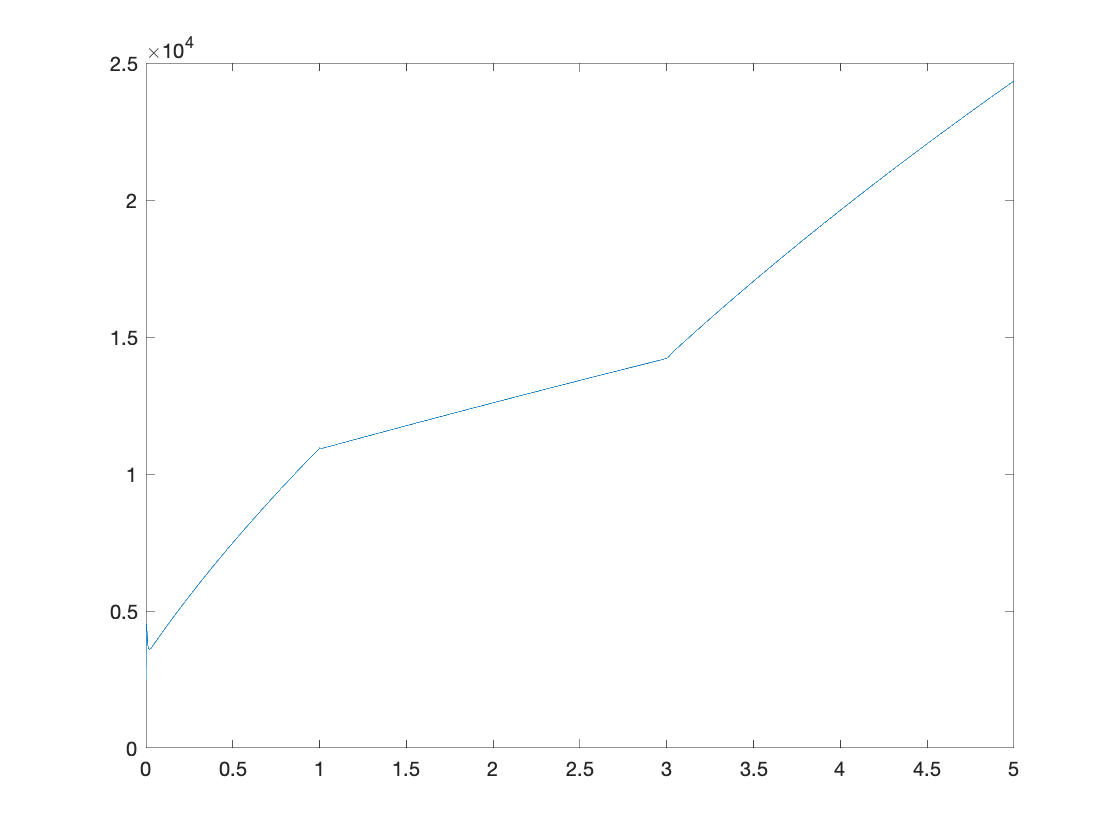

plot(tV, res(:,11))

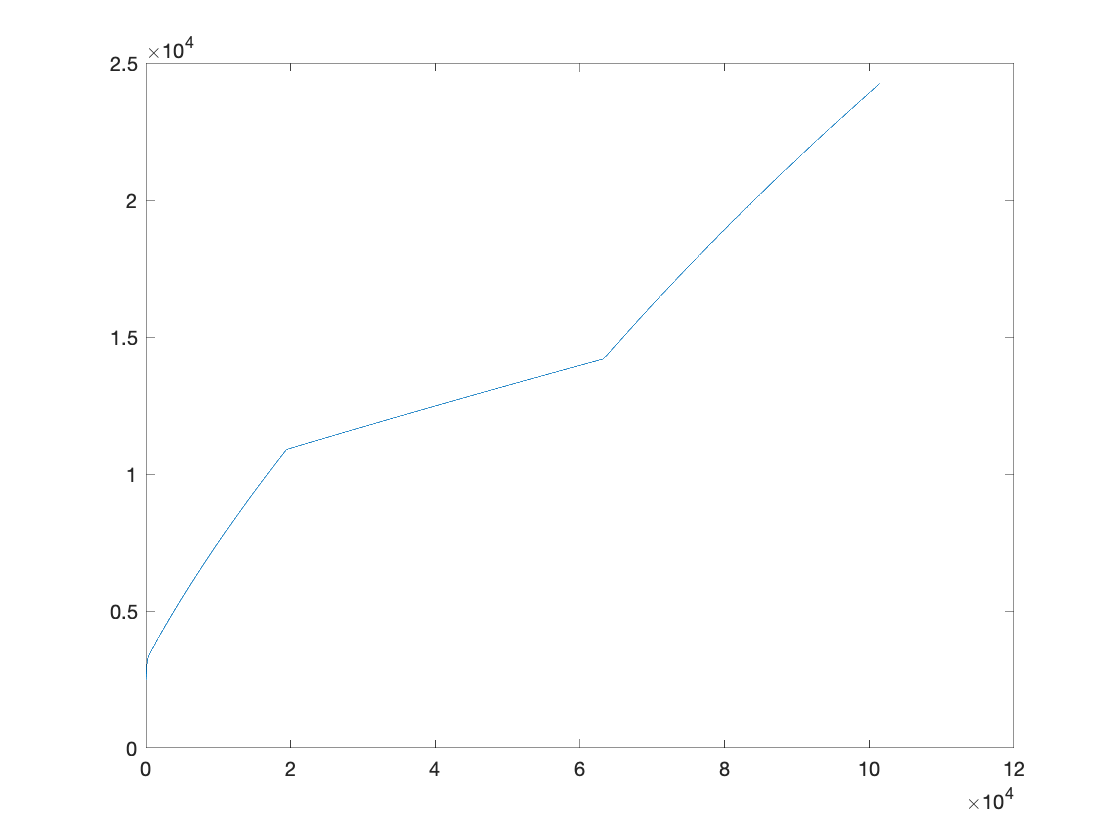

plot(res(:,12))

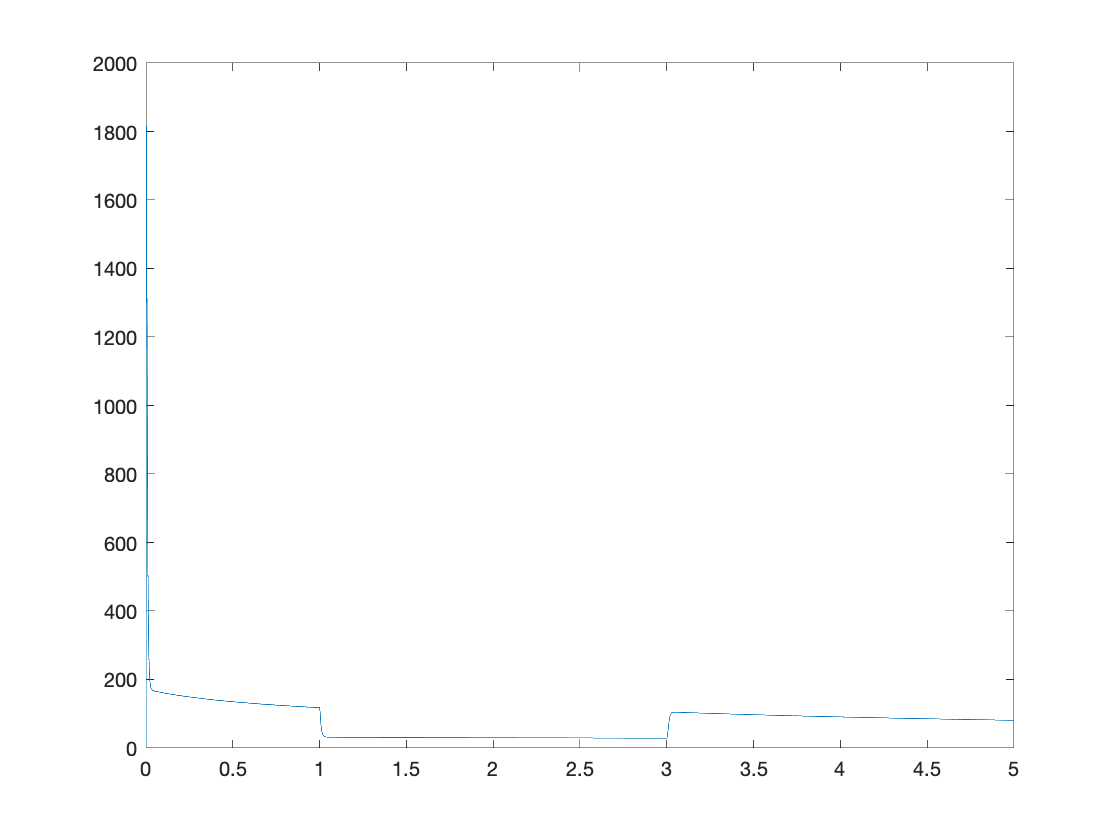

plot(tV, res(:,11) - res(:,12))

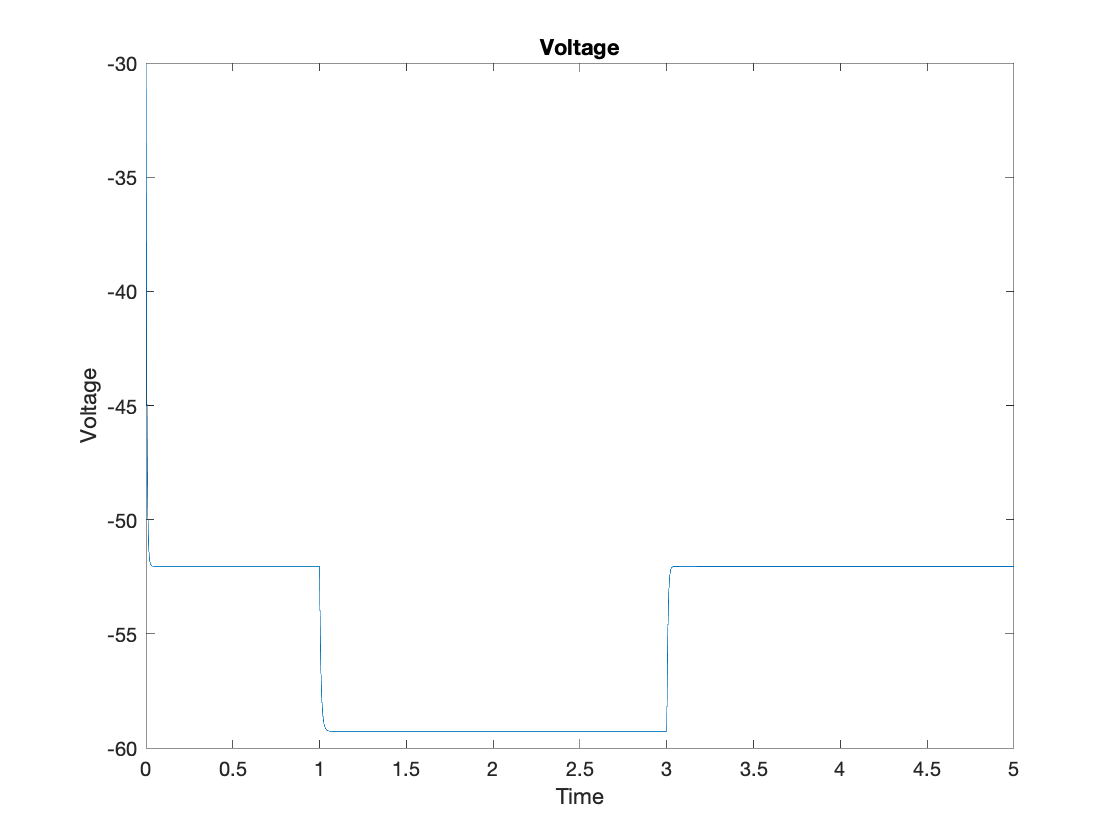

plot(tV, V)

title('Voltage')
xlabel('Time')
ylabel('Voltage')

*Delayed rectifying potassium current*

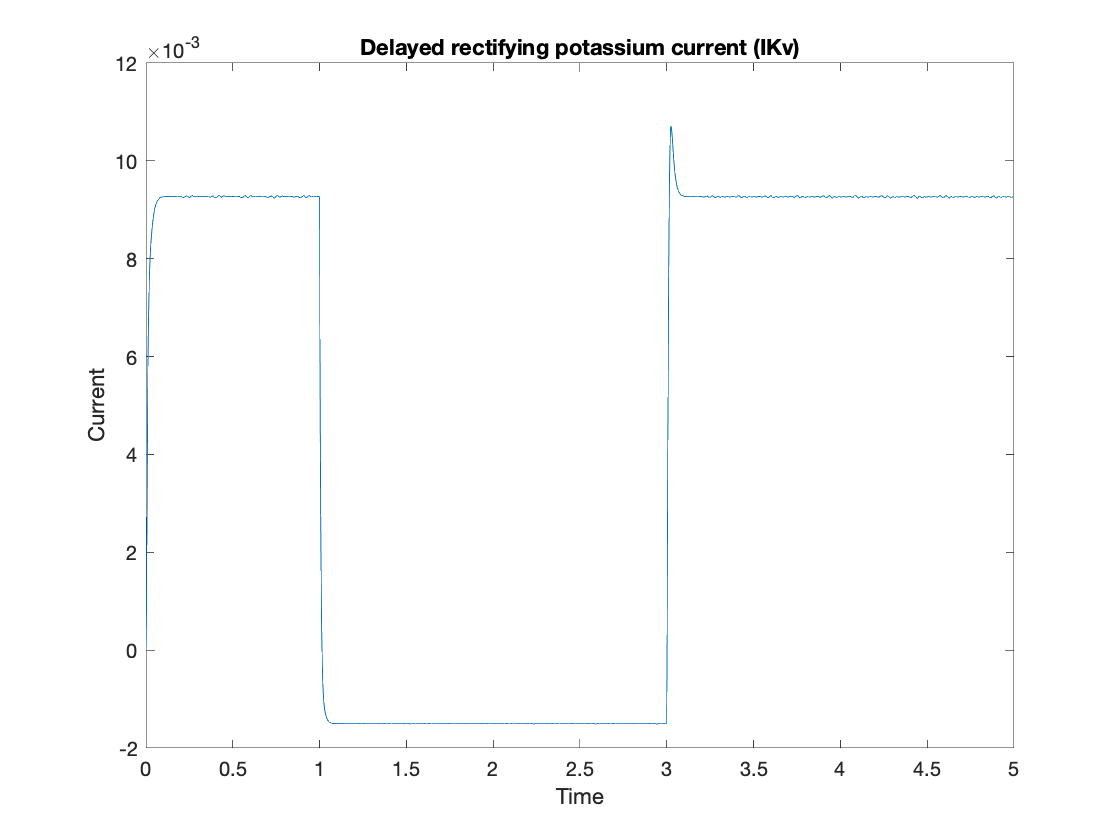

[t, IKv] = calcIKv(tspan, tV, V);
plot(t, IKv)

title('Delayed rectifying potassium current (IKv)')
xlabel('Time')
ylabel('Current')

*Hyperpolarization activated current*

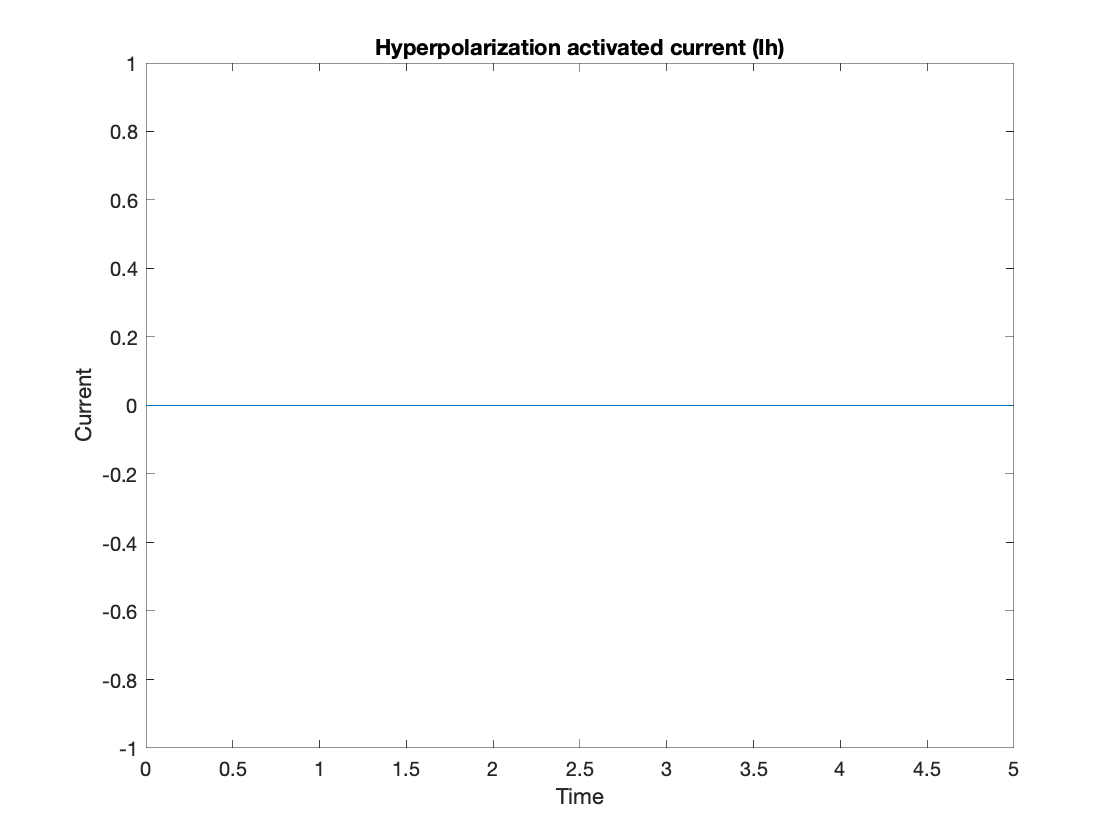

[t, Ih] = calcIh(tspan, tV, V);
plot(t, Ih)

title('Hyperpolarization activated current (Ih)')
xlabel('Time')
ylabel('Current')

*Calcium current*

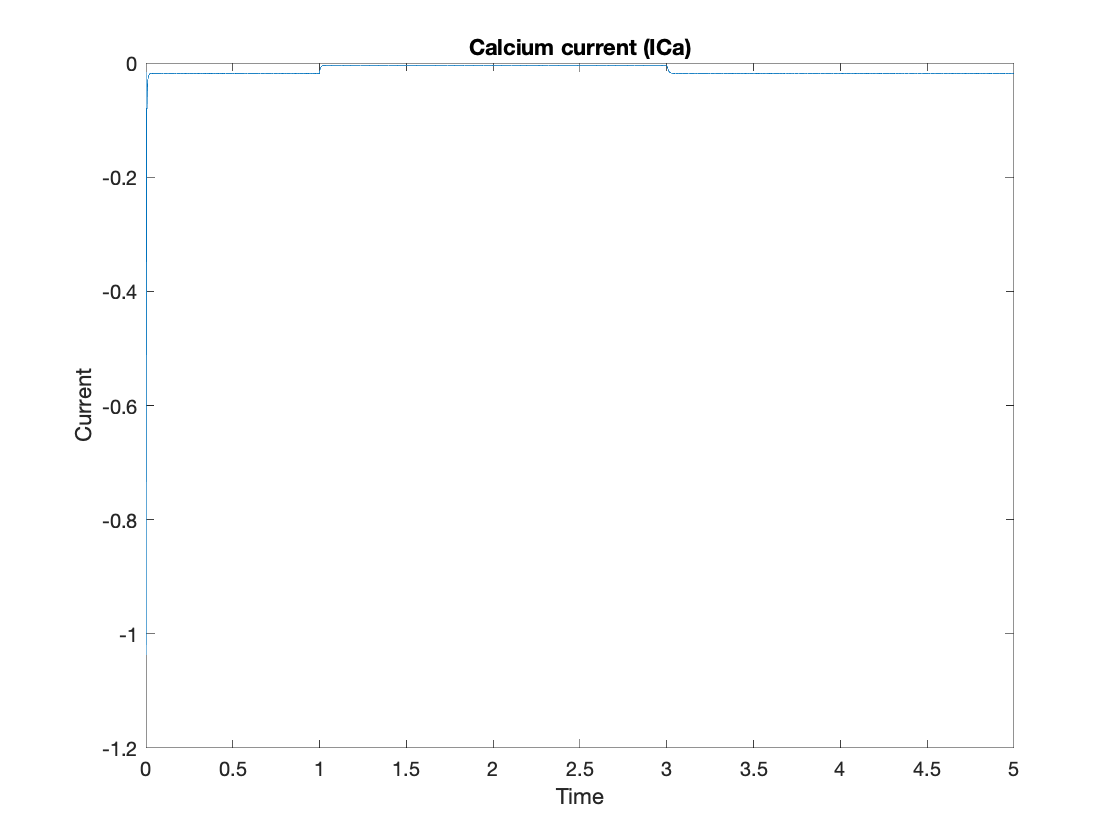

[t, ICa] = calcICa(tspan, tV, V);
plot(t, ICa)

title('Calcium current (ICa)')
xlabel('Time')
ylabel('Current')

*Calcium-dependent K current*

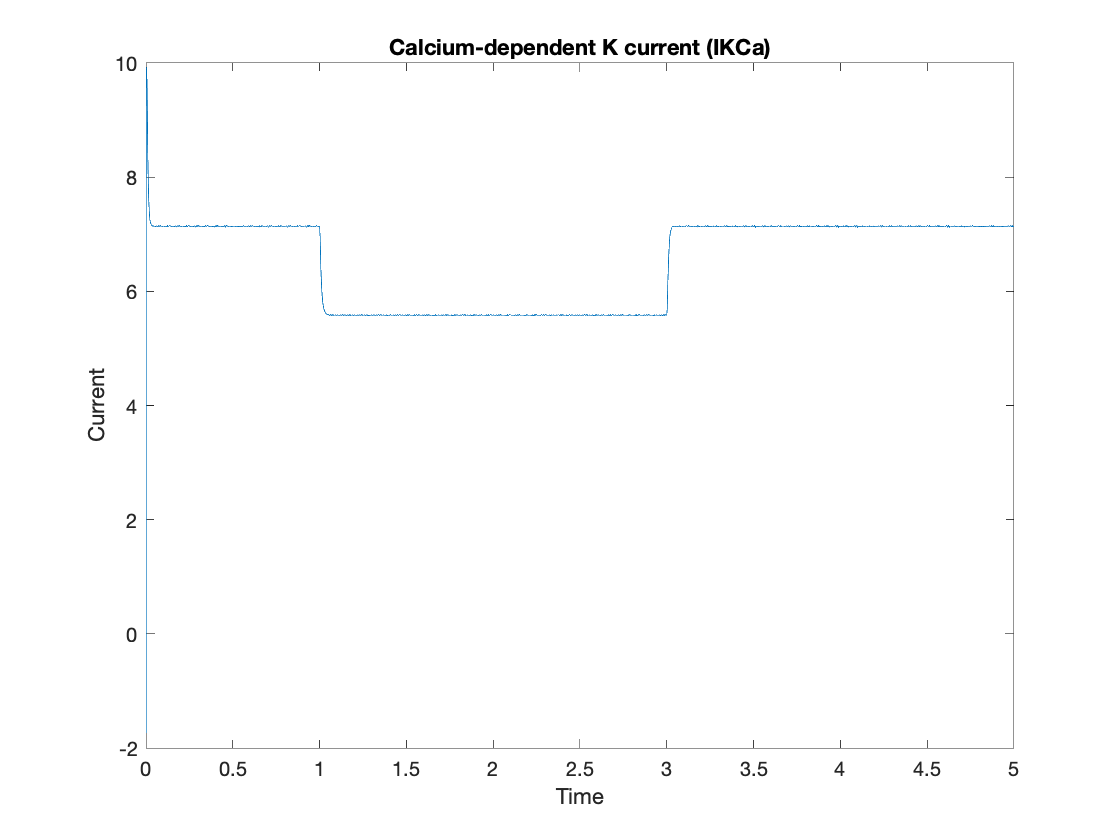

[t, IKCa] = calcIKCa(tspan, tV, V);
plot(t, IKCa)

title('Calcium-dependent K current (IKCa)')
xlabel('Time')
ylabel('Current')

*Leakage current*

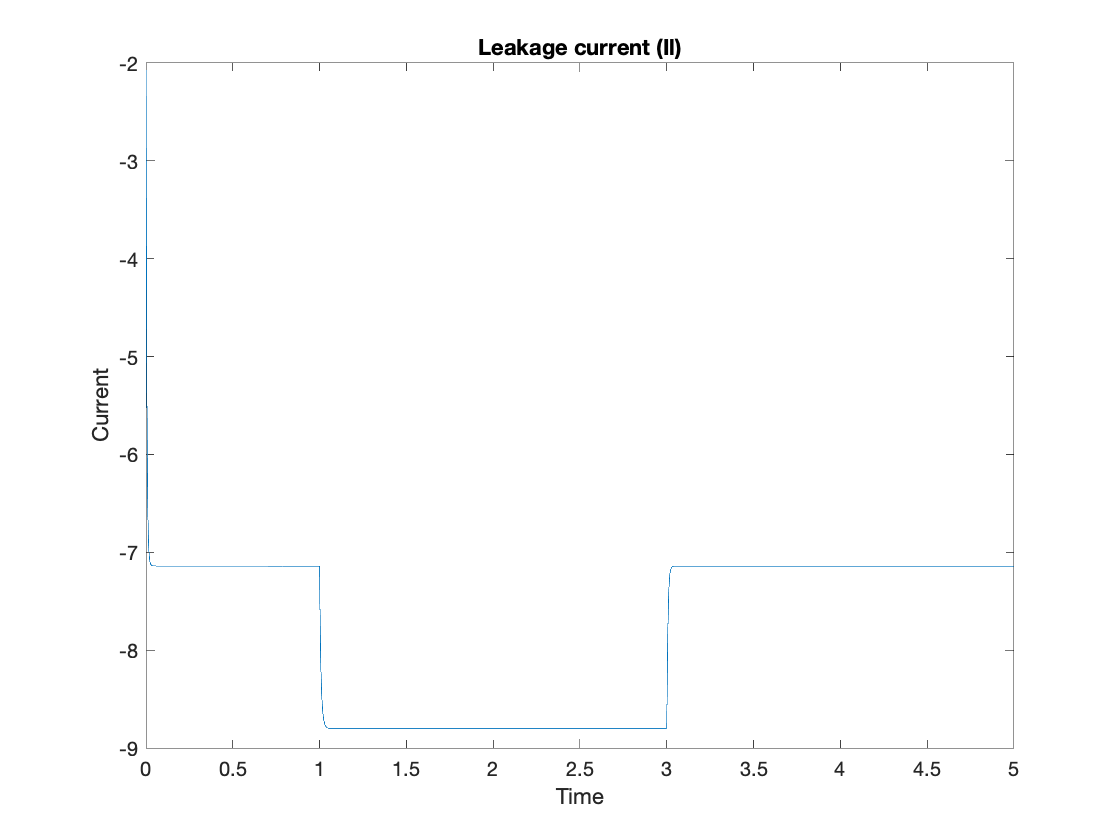

Il = calcIl(V);
plot(tV, Il)

title('Leakage current (Il)')
xlabel('Time')
ylabel('Current')

*Transient outward current (not needed to calculate voltage)*

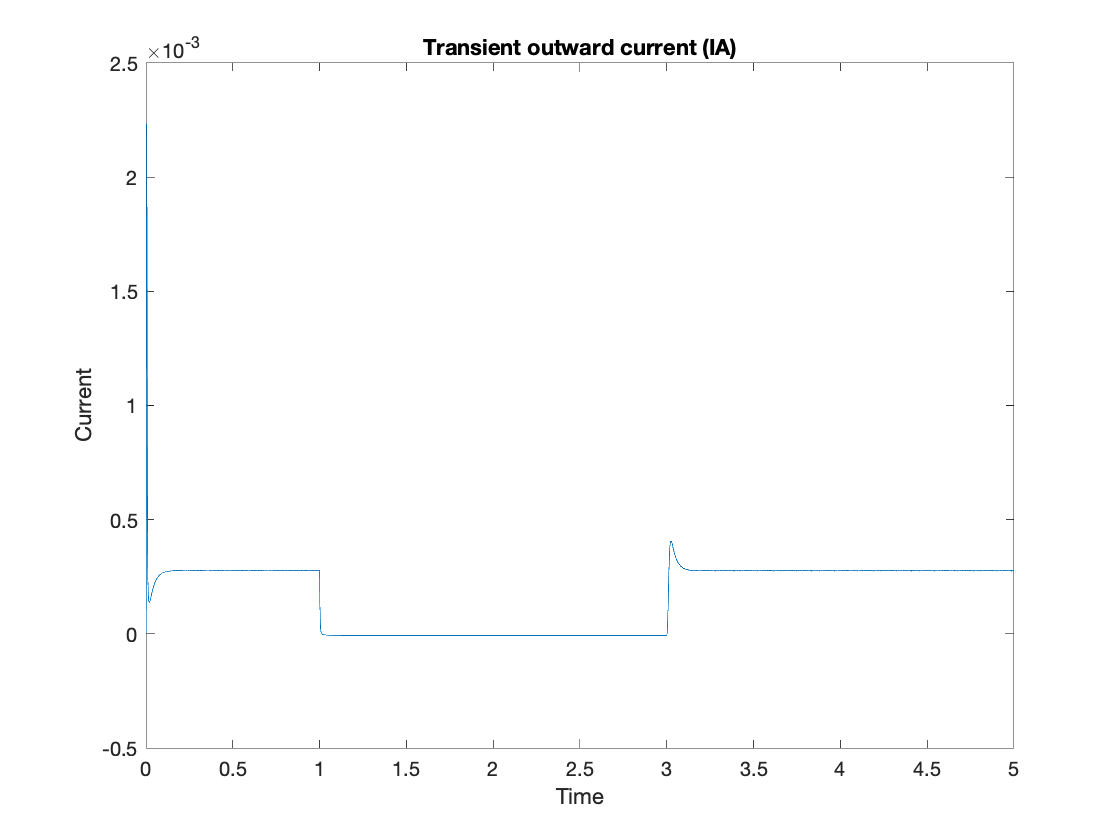

[t, IA] = calcIA(tspan, tV, V);
plot(t, IA)

title('Transient outward current (IA)')
xlabel('Time')
ylabel('Current')